# Actividad #10

**Actividad grupal de Data Forecasting**

- Nombre 1:

- Nombre 2:

- Nombre 3:

- Fecha:

- Reposiroty: [https://github.com/vasanza/SSE](https://github.com/vasanza/SSE)

- Refrence: [https://github.com/vasanza/Matlab_Code/tree/main](https://github.com/vasanza/Matlab_Code/tree/main)

- Dataset: [Open Energy Data Initiative (OEDI)](https://data.openei.org/)

- [Photovoltaic Data Acquisition (PVDAQ) Public Datasets](https://data.openei.org/s3_viewer?bucket=oedi-data-lake&prefix=pvdaq%2F2023-solar-data-prize%2F2105_OEDI%2Fdata%2F)

## Descripción:

##  Objetivos:

- Enfocarnos en la prediccion de datos "**Data Forecasting**"

- Definir el dataset a utilizar

- Determinar el periodo de tiempo que se desea hacer forecasting

- Determinar las variables de entrada (input) y de salida (output) de un sistema de caja negra

- Dividir el data en 70% para entrenar el modelo (training_data)

- Dividir el restante 30% para validar el modelo (testing_data)

- Utilizar el toolbox **"regressionLearner"** de Matlab, para entrenar **26 **modelos de Forecasting

- Seleccionar el mejor modelo de Data Forecasting basado en el RMSE (Root Mean Squared Error)

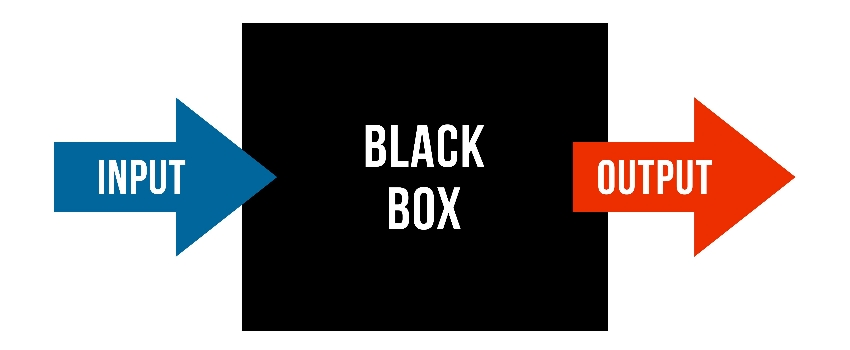

## Tipo de Dataset a utilizar:

- Cada columna representa una variable y cada fila representa una muestra (frecuencia de mestreo constante)

- La primera columna es el TimeStamp. Ejemplo: 'dd-MMM-yyyy HH:mm:ss.SSS'

- El arhivo debe estar en formato **.csv**, si es otro formato de debera convertir a .csv. Ejemplo: si es **.parqet**, se lo convierte con esta pagina [https://table.studio/convert/parquet/to/csv](https://table.studio/convert/parquet/to/csv)

- Si existen multiples archivos .csv, estos se deberan colocar en la carpeta data, siempre que esten relacionadas a un mismo sistema. **Ejemplo de regresion**: consumo_enero_2025.csv, consumo_febrero_2025.csv, etc. **Ejemplo de clasificacion**: consumo_casa_enero_2025.csv, sonsumo_escuela_enero_2025.csv, etc.

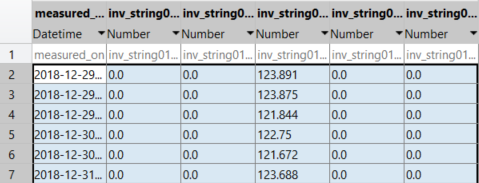

## **Copia la actividad en tu respaldo**

%Configuracion de carpeta ./src para librerias
addpath(genpath('./src'));

% Definir rutas
miRespaldo = 'C:\Desktop\SSE_vic';  %<========
repositorio = 'C:\Desktop\SSE\2025';%<========

if true
    % repositorio -> respaldo
    git_sse(miRespaldo)

filename = struct with fields:
       name: '2105_inv01_data.csv'
     folder: 'C:\Users\victo\Desktop\SSE\2025\ACTIVIDAD10\data'
       date: '20-Jun-2025 19:15:47'
      bytes: 18694812
      isdir: 0
    datenum: 7.3979e+05


else

maxFiles = 1

    % Mombre de la carpeta de la Actividad en el repositorio
    nombreCarpeta = string(split(cd, filesep));
    nombreCarpeta = nombreCarpeta(end) % Nombre de la carpeta
    % Regresar al repositorio
    cd(fullfile(repositorio,nombreCarpeta))
end

pathFile = '.\data\2105_inv01_data.csv'

## Desarrollo de la Actividad

#### **Paso 1: Borrar variables en el workspace y limpiar cmd**

clear % Borrar variables en el workspace y libera memoria RAM
clc % Limpia el Command Window

#### Paso 2: Configuración de carpeta ./src para librerias

addpath(genpath('./src'));

ans =   TableProperties with properties:

             Description: ''
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {1×6 cell}
    VariableDescriptions: {1×6 cell}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {}
        CustomProperties: No custom properties are set.
      Use addprop and rmprop to modify CustomProperties.


#### Paso 3: Configuración de carpeta ./data para datasets

datapath = fullfile('./data/');

#### Paso 4: Buscar nombres de archivos .csv en ./data

filename = FindCSV(datapath)

VariableNames = 1×6 cell array
    {'measured_on'}    {'inv_string01_ac_output__kwh__inv_150164'}    {'inv_string01_ac_output__power_factor__inv_150165'}    {'inv_string01_ac_voltage__v__inv_150163'}    {'inv_string01_dc_voltage__v__inv_150162'}    {'inv_string01_temperature__c__inv_150166'}


maxFiles = size(filename,1)

#### Paso 5: Cargar automaticamente todos los archivos csv desde ./data

allData = [];

samples = 20000

for i=1:maxFiles
    nameFile = filename(i).name;
    pathFile = strcat(datapath, nameFile)
    rawData = fLoad_dataset(pathFile);
    allData = [allData; rawData];
end
clear rawData nameFile filename; 

#### Paso 6: Extraer y graficar las variables

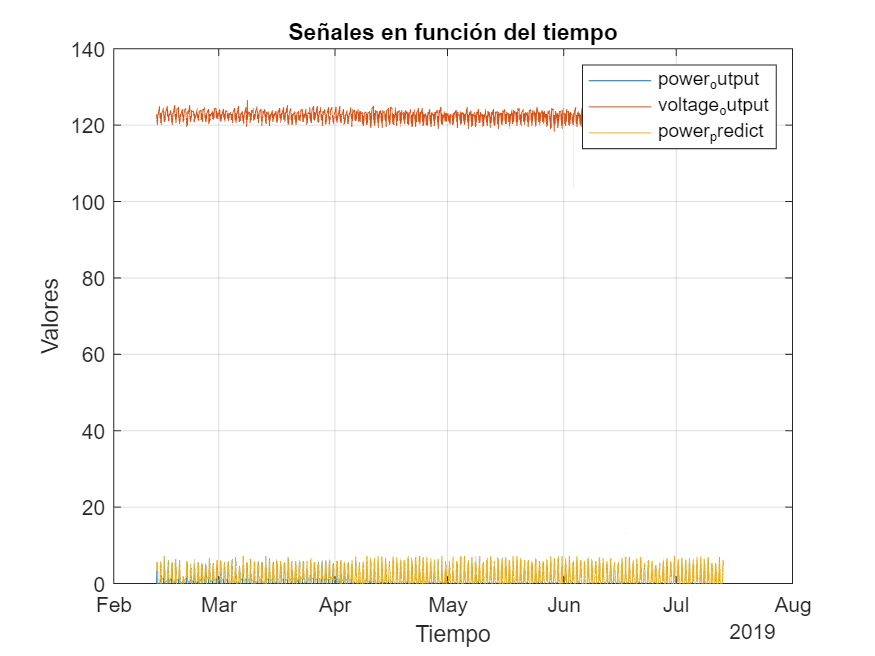

allData.Properties
t = datetime(allData.measured_on);
VariableNames = allData.Properties.VariableNames
maxSamples = size(allData,1);
samples = 20000
step = 4; %Representa un periodo de sampleo (15min)

% Inputs_Variables
power_output = allData{:,VariableNames(2)};
power_output(isnan(power_output)) = 0;  % Preprocesamiento (Reemplazar NaN con 0)
power_output = power_output(1:samples - step); % sig 15min (step)

voltage_output = allData{:,VariableNames(4)};
voltage_output(isnan(voltage_output)) = 0;  % Preprocesamiento (Reemplazar NaN con 0)
voltage_output = voltage_output(1:samples - step); % sig 15min (step)

% Output_Variables
power_predict = allData{:,VariableNames(2)};
power_predict(isnan(power_predict)) = 0;  % Preprocesamiento (Reemplazar NaN con 0)
power_predict = power_predict(1 + step:samples); % sig 15min (step)


% Dataset [Inputs_Variables Output_Variables]
dataset = [power_output voltage_output power_predict];

ans =        19996           3



% Graficar dataset

ans =        13997           3


figure;
plot(t(1:samples - step,:),dataset); % las 1k primeras filas

ans =         6000           3


legend("power_output","voltage_output","power_predict");
xlabel('Tiempo');
ylabel('Valores');
title('Señales en función del tiempo');
grid on;

#### Paso 7: Dividir el dataset en training_data y testing_data

size(dataset)
training_data = dataset(1:round(end*0.7),:); % 70% de datos para entrenar
size(training_data)
testing_data = dataset(round(end*0.7):end,:);% 30% de datos para testing
size(testing_data)

#### Paso 8: Utilizar el toolbox **"regressionLearner"**

regressionLearner